**Read in first engine data**

% read in data
sensorData = readtable('CMAPSSData/train_FD001.txt')

sensorData =     Var1    Var2     Var3       Var4      Var5     Var6      Var7      Var8      Var9     Var10    Var11    Var12     Var13     Var14     Var15    Var16    Var17     Var18     Var19     Var20     Var21    Var22    Var23    Var24    Var25    Var26     Var27
    ____    ____    _______    _______    ____    ______    ______    ______    ______    _____    <s

sensorData = sensorData(:,1:26)

sensorData =     Var1    Var2     Var3       Var4      Var5     Var6      Var7      Var8      Var9     Var10    Var11    Var12     Var13     Var14     Var15    Var16    Var17     Var18     Var19     Var20     Var21    Var22    Var23    Var24    Var25    Var26 
    ____    ____    _______    _______    ____    ______    ______    ______    ______    _____    _____    <s

sensorData.Properties.VariableNames = { ...
    'Unit', ...
    'Time', ...
    'Setting1', ... 
    'Setting2', ...
    'Setting3', ...
    'FanInletTemp', ...
    'LPCOutletTemp', ... 
    'HPCOutletTemp', ... 
    'LPTOutletTemp', ... 
    'FanInletPres', ... 
    'BypassDuctPres', ... 
    'TotalHPCOutletPres', ... 
    'PhysFanSpeed', ... 
    'PhysCoreSpeed', ... 
    'EnginePresRatio', ... 
    'StaticHPCOutletPres', ... 
    'FuelFlowRatio', ... 
    'CorrFanSpeed', ... 
    'CorrCoreSpeed', ... 
    'BypassRatio', ... 
    'BurnerFuelAirRatio', ... 
    'BleedEnthalpy', ... 
    'DemandFanSpeed', ... 
    'DemandCorrFanSpeed', ... 
    'HPTCoolantBleed', ... 
    'LPTCoolantBleed' ...
}

sensorData =     Unit    Time    Setting1    Setting2    Setting3    FanInletTemp    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    FanInletPres    BypassDuctPres    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    EnginePresRatio    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BurnerFuelAirRatio    BleedEnthalpy    DemandFanSpeed    DemandCorrFanSpeed    HPTCoolantBleed    LPTCoolantBleed
    ____    ____    ________    ________    

engine01 = sensorData(sensorData.Unit==1,1:26)

engine01 =     Unit    Time    Setting1    Setting2    Setting3    FanInletTemp    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    FanInletPres    BypassDuctPres    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    EnginePresRatio    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BurnerFuelAirRatio    BleedEnthalpy    DemandFanSpeed    DemandCorrFanSpeed    HPTCoolantBleed    LPTCoolantBleed
    ____    ____    ________    ________    <s

**View subset ****of sensor signals**

for ii = 1:9
    subplot(3,3,ii)
    plot(engine01.Time, engine01{:,5+ii})
    title(engine01.Properties.VariableNames{5+ii})
    xlabel('Time')
    xlim([0,125])
end

**Select relevant variable names based on visualization**

variableNames = { ...
    'Unit', ...
    'Time', ...
    'LPCOutletTemp', ... 
    'HPCOutletTemp', ... 
    'LPTOutletTemp', ...  
    'TotalHPCOutletPres', ... 
    'PhysFanSpeed', ... 
    'PhysCoreSpeed', ... 
    'StaticHPCOutletPres', ... 
    'FuelFlowRatio', ... 
    'CorrFanSpeed', ... 
    'CorrCoreSpeed', ... 
    'BypassRatio', ... 
    'BleedEnthalpy', ... 
    'HPTCoolantBleed', ... 
    'LPTCoolantBleed' ...
}

variableNames =     'Unit'    'Time'    'LPCOutletTemp'    'HPCOutletTemp'    'LPTOutletTemp'    'TotalHPCOutletPres'    'PhysFanSpeed'    'PhysCoreSpeed'    'StaticHPCOutletPres'    'FuelFlowRatio'    'CorrFanSpeed'    'CorrCoreSpeed'    'BypassRatio'    'BleedEnthalpy'    'HPTCoolantBleed'    'LPTCoolantBleed'


engine01 = engine01(:, variableNames)

engine01 =     Unit    Time    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed
    ____    ____    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    ________

**Remove noise**

% Smooth sensor data
engine01_smooth = engine01

engine01_smooth =     Unit    Time    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed
    ____    ____    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _

engine01_smooth{:,3:end} = movmean(engine01_smooth{:,3:end},[4,0])

engine01_smooth =     Unit    Time    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed
    ____    ____    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _

engine01_smooth(1:5,:) = []

engine01_smooth =     Unit    Time    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed
    ____    ____    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _

**Plot smoothed data**

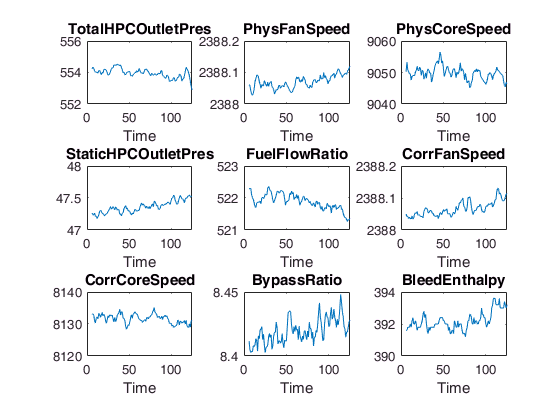

for ii = 1:9
    subplot(3,3,ii)
    plot(engine01_smooth.Time, engine01_smooth{:,5+ii})
    title(engine01_smooth.Properties.VariableNames{5+ii})
    xlabel('Time')
    xlim([0,125])
end

**Monitoring equipment - control charts**

%controlchart(sensorData.LPCOutletTemp,'chart','1')

Error using internal.stats.getParamVal (line 25)
'1' is not a valid value for the CHARTTYPE argument.

Error in controlchart>getctypeinfo (line 432)
[cctypes,locs] = internal.stats.getParamVal(charttype,cclist,'CHARTTYPE',true);

Error in 

**Read all data**

% 